clear
clf

% 1. Color Gamut
load("Dell.mat")
load("Inkjet.mat")

plot_chrom(XYZdell, 'blue')
plot_chrom(XYZinkjet, 'red')

**Answer:**

Red: They're both about the same in ability to reproduce red.

Green: The inkjet should be better at reproducing green, but neither of them are particularly good.

Blue: The dell should be better at reproducing blue.

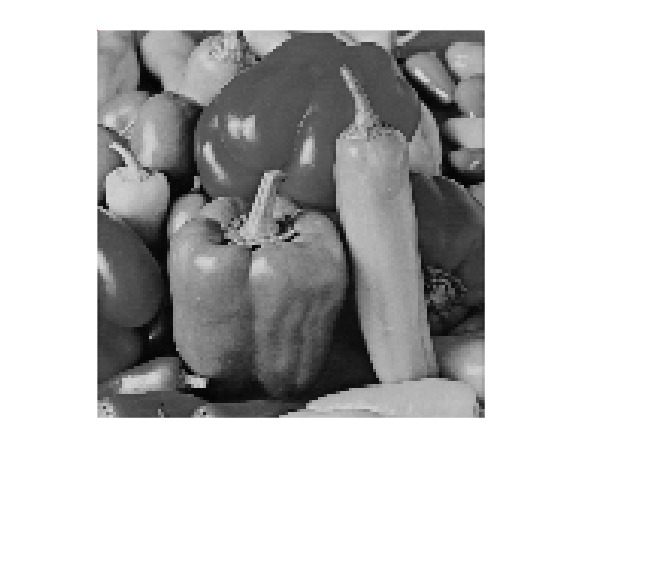

% 2. Mathematical metrics

% 2.1
peppers_gray = im2double(imread("peppers_gray.tif"));

% 2.1.1
peppers_gray_nearest = imresize(imresize(peppers_gray,0.25,'nearest'),4,'nearest');
imshow(peppers_gray_nearest)

mysnr(peppers_gray, abs(peppers_gray-peppers_gray_nearest))

ans = 17.0956

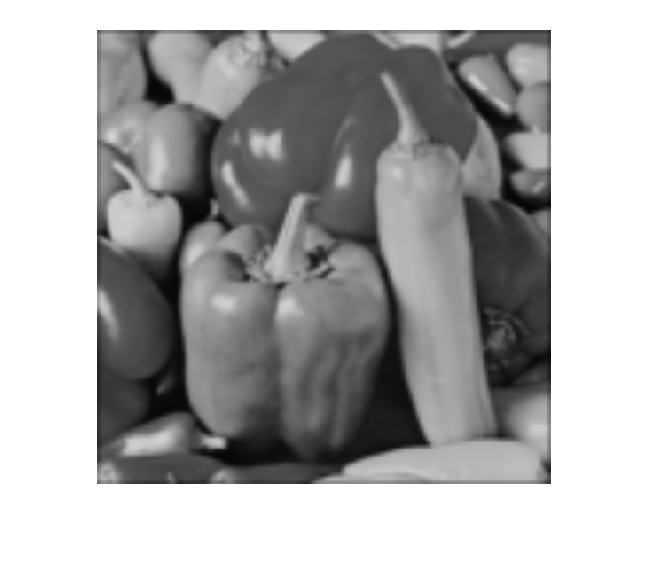


peppers_gray_bilinear = imresize(imresize(peppers_gray,0.25,'bilinear'),4,'bilinear');
imshow(peppers_gray_bilinear)

mysnr(peppers_gray, abs(peppers_gray-peppers_gray_bilinear))

ans = 18.8922

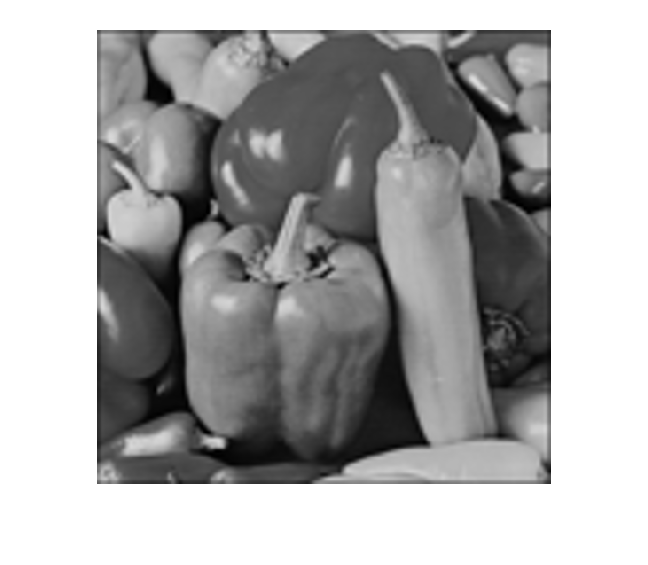


peppers_gray_bicubic = imresize(imresize(peppers_gray,0.25,'bicubic'),4,'bicubic');
imshow(peppers_gray_bicubic)

mysnr(peppers_gray, abs(peppers_gray-peppers_gray_bicubic))

ans = 19.8538

**Answer:** They are pretty similar, but the third is the best, which is also the result from SNR.

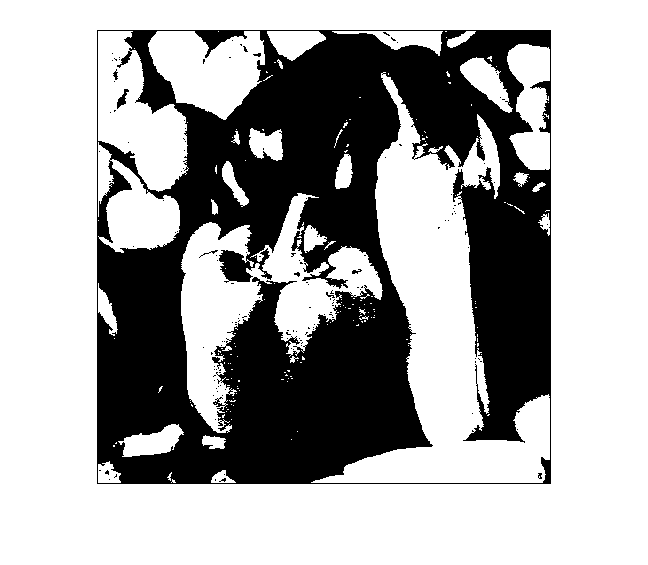

% 2.1.2
peppers_halftone = im2double((peppers_gray >= 0.5));
imshow(peppers_halftone)

mysnr(peppers_gray, abs(peppers_gray-peppers_halftone))

ans = 2.9721

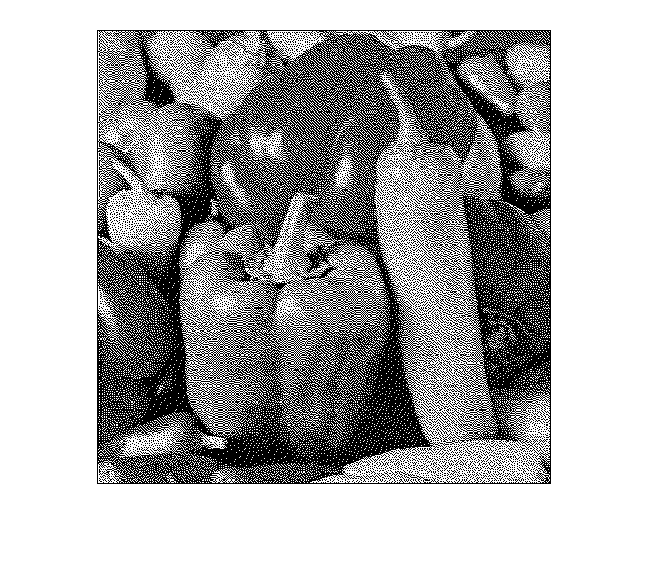


peppers_dither = im2double(dither(peppers_gray));
imshow(peppers_dither)

mysnr(peppers_gray, abs(peppers_gray-peppers_dither))

ans = 0.4112

**Answer:** We do not believe that SNR can be trusted in this case. The second image appears better to the human eye but has a lower SNR value. For changing the halftone value, all values other than 0.5 look worse but have higher SNR (at least for <0.5)

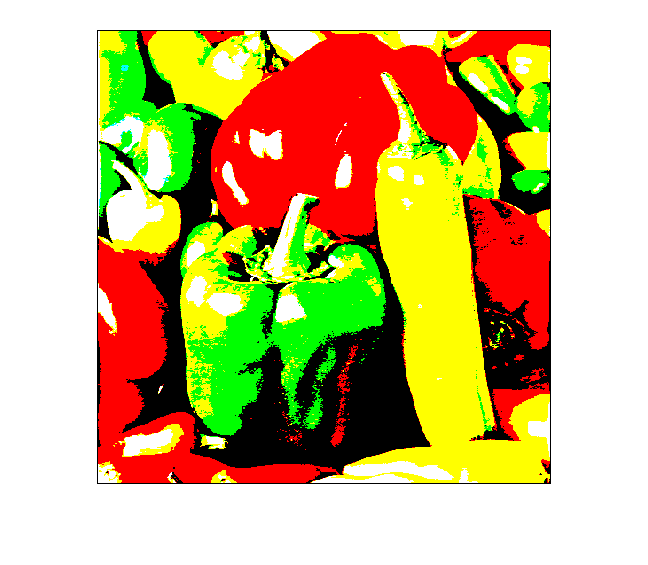

% 2.2
peppers_color = im2double(imread("peppers_color.tif"));

for channel = 1:3
    peppers_colorhalftone(:,:,channel) = im2double((peppers_color(:,:,channel) >= 0.5));
end
imshow(peppers_colorhalftone)

mysnr(peppers_color, abs(peppers_color-peppers_colorhalftone))

ans = 4.3188

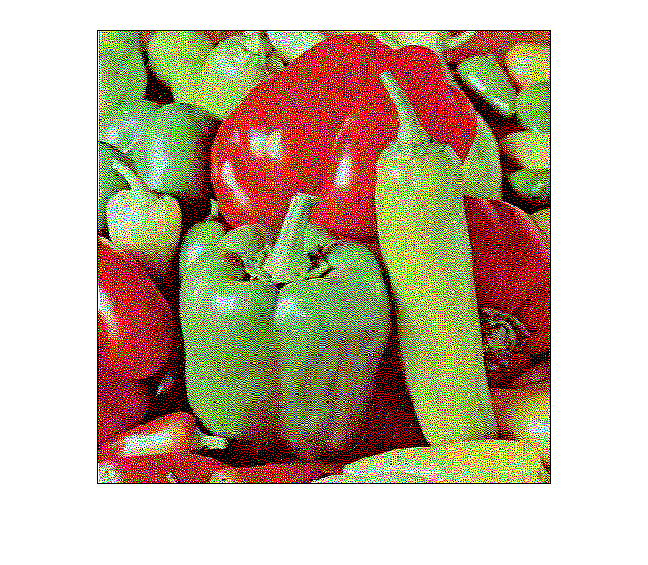


for channel = 1:3
    peppers_colordither(:,:,channel) = double(dither(peppers_color(:,:,channel)));
end
imshow(peppers_colordither)

mysnr(peppers_color, abs(peppers_color-peppers_colordither))

ans = 1.3304


peppers_lab = rgb2lab(peppers_color);
peppers_labhalftone = rgb2lab(peppers_colorhalftone);
peppers_labdither = rgb2lab(peppers_colordither);

deltaE = sqrt((peppers_lab(:,:,1) - peppers_labhalftone(:,:,1)).^2 + (peppers_lab(:,:,2) - peppers_labhalftone(:,:,2)).^2 + (peppers_lab(:,:,3) - peppers_labhalftone(:,:,3)).^2);
mean(mean(deltaE))

ans = 50.1577

max(max(deltaE))

ans = 120.1919

deltaE = sqrt((peppers_lab(:,:,1) - peppers_labdither(:,:,1)).^2 + (peppers_lab(:,:,2) - peppers_labdither(:,:,2)).^2 + (peppers_lab(:,:,3) - peppers_labdither(:,:,3)).^2);
mean(mean(deltaE))

ans = 72.8423

max(max(deltaE))

ans = 203.6272

**Answer:** If the dithered color image is still perceived to be better, neither SNR nor delta E seem to agree.

% 3. Mathematical metrics involving HVS
for channel = 1:3
    halftone(:,:,channel) = snr_filter(peppers_color(:,:,channel), peppers_color(:,:,channel)-peppers_colorhalftone(:,:,channel));
end
mean(halftone)

ans = 4.2630


for channel = 1:3
    dither(:,:,channel) = snr_filter(peppers_color(:,:,channel), peppers_color(:,:,channel)-peppers_colordither(:,:,channel));
end
mean(dither)

ans = 13.1627

Now it says that the dither is better, which we agree with.

f=MFTsp(15,0.0847,500);
for channel = 1:3
    hvs_rgb(:,:,channel) = conv2(peppers_color(:,:,channel),f,'same');
    %hvs_rgb(:,:,channel) = (hvs_rgb(:,:,channel) > 0).*hvs_rgb(:,:,channel);

    hvs_halftone(:,:,channel) = conv2(peppers_colorhalftone(:,:,channel),f,'same');
    %hvs_halftone(:,:,channel) = (hvs_halftone(:,:,channel) > 0).*hvs_halftone(:,:,channel);

    hvs_dither(:,:,channel) = conv2(peppers_colordither(:,:,channel),f,'same');
    %hvs_dither(:,:,channel) = (hvs_dither(:,:,channel) > 0).*hvs_dither(:,:,channel);
end

hvs_rgb = rgb2lab(hvs_rgb);
hvs_halftone = rgb2lab(hvs_halftone);
hvs_dither = rgb2lab(hvs_dither);

deltaE = sqrt((hvs_rgb(:,:,1) - hvs_halftone(:,:,1)).^2 + (hvs_rgb(:,:,2) - hvs_halftone(:,:,2)).^2 + (hvs_rgb(:,:,3) - hvs_halftone(:,:,3)).^2);
mean(mean(deltaE))

ans = 48.1629

max(max(deltaE))

ans = 105.7033

deltaE = sqrt((hvs_rgb(:,:,1) - hvs_dither(:,:,1)).^2 + (hvs_rgb(:,:,2) - hvs_dither(:,:,2)).^2 + (hvs_rgb(:,:,3) - hvs_dither(:,:,3)).^2);
mean(mean(deltaE))

ans = 20.2117

max(max(deltaE))

ans = 83.1636

**Answer:** Now the second image is better with a lower value.

% 4. S-CIELab

% 4.1
pctif = im2double(imread("peppers_color.tif"));
pc_xyz = rgb2xyz(pctif);
pcresize_xyz_nearest = rgb2xyz(imresize(imresize(pctif,0.25,'nearest'),4,'nearest'));
pcresize_xyz_bilinear = rgb2xyz(imresize(imresize(pctif,0.25,'bilinear'),4,'bilinear'));
pcresize_xyz_bicubic = rgb2xyz(imresize(imresize(pctif,0.25,'bicubic'),4,'bicubic'));


sampPerDeg = 141.21 * 500/25.4 * tan(pi/180);

fullmetric = scielab(sampPerDeg, pc_xyz, pcresize_xyz_nearest, [95.05, 100, 108.9], 'xyz');

Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


mean(mean(fullmetric))

ans = 0.1918

fullmetric = scielab(sampPerDeg, pc_xyz, pcresize_xyz_bilinear, [95.05, 100, 108.9], 'xyz');

Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


mean(mean(fullmetric))

ans = 0.2024

fullmetric = scielab(sampPerDeg, pc_xyz, pcresize_xyz_bicubic, [95.05, 100, 108.9], 'xyz');

Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


mean(mean(fullmetric))

ans = 0.1307

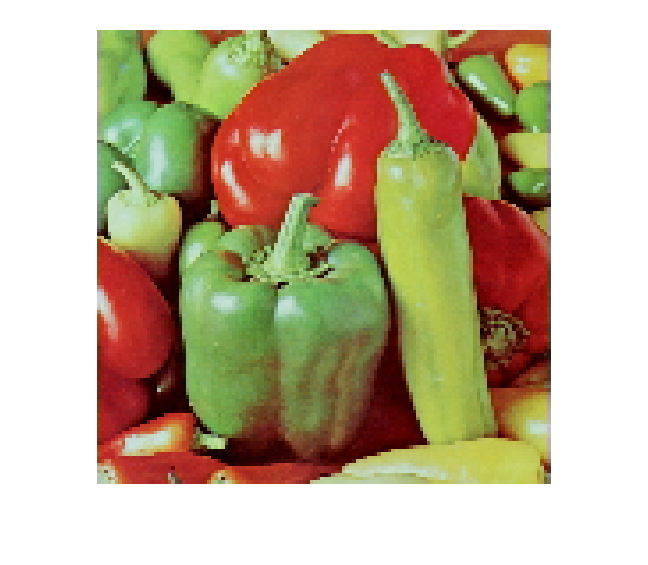


imshow(imresize(imresize(pctif,0.25,'nearest'),4,'nearest'))

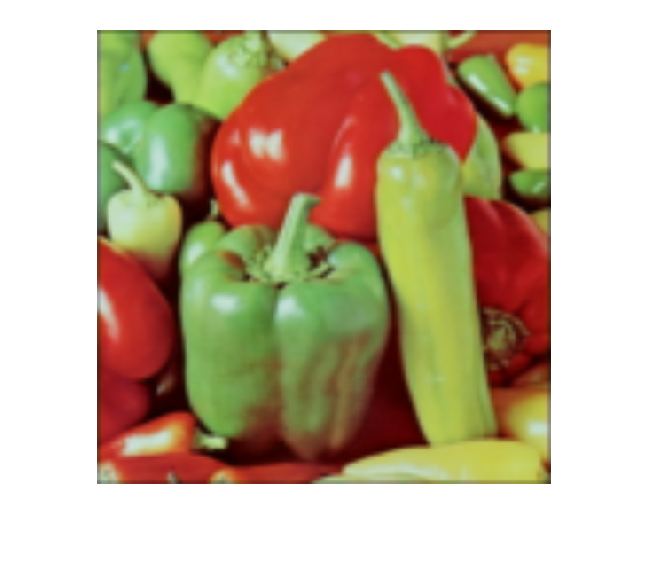

imshow(imresize(imresize(pctif,0.25,'bilinear'),4,'bilinear'))

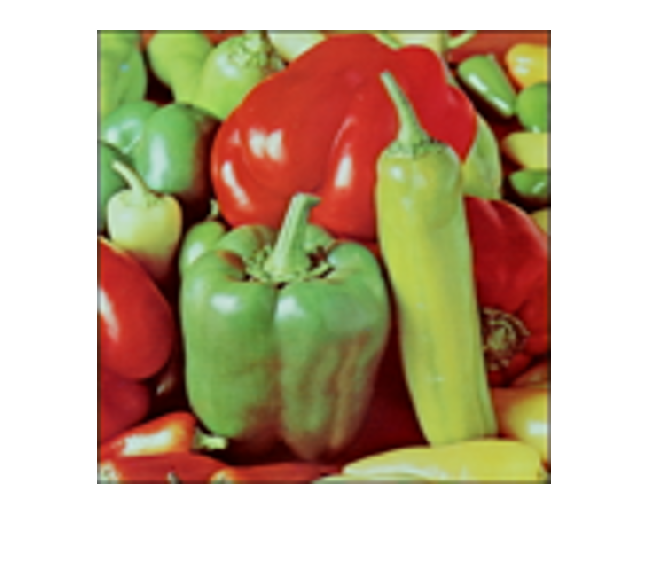

imshow(imresize(imresize(pctif,0.25,'bicubic'),4,'bicubic'))

**Answer:** Full metric seems to want the first image to be better, but it has visible corners.

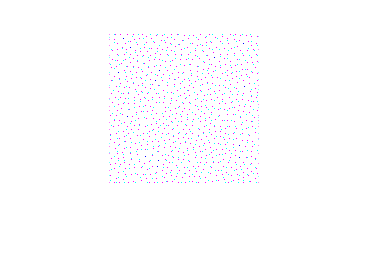

% 4.2
load("colorhalftones.mat")

imshow(c1)

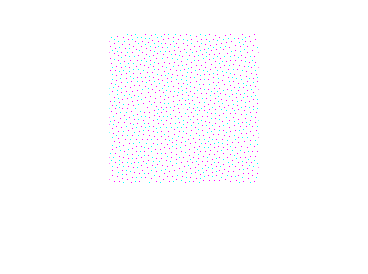

imshow(c2)

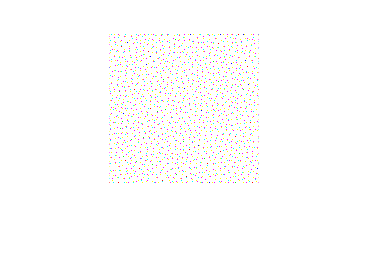

imshow(c3)

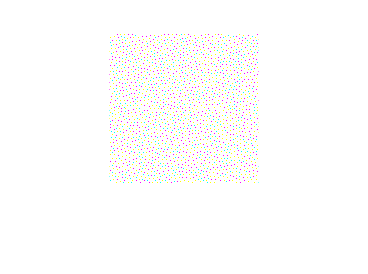

imshow(c4)

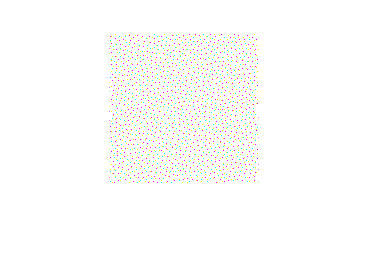

imshow(c5)


c1metric = scielab(sampPerDeg, rgb2xyz(c1));

Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...


c1sum = std2(c1metric(:,:,1)) + std2(c1metric(:,:,2)) + std2(c1metric(:,:,3))

c1sum = 0.0302


c2metric = scielab(sampPerDeg, rgb2xyz(c2));

Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...


c2sum = std2(c2metric(:,:,1)) + std2(c2metric(:,:,2)) + std2(c2metric(:,:,3))

c2sum = 0.0255


c3metric = scielab(sampPerDeg, rgb2xyz(c3));

Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...


c3sum = std2(c3metric(:,:,1)) + std2(c3metric(:,:,2)) + std2(c3metric(:,:,3))

c3sum = 0.0313


c4metric = scielab(sampPerDeg, rgb2xyz(c4));

Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...


c4sum = std2(c4metric(:,:,1)) + std2(c4metric(:,:,2)) + std2(c4metric(:,:,3))

c4sum = 0.0320


c5metric = scielab(sampPerDeg, rgb2xyz(c5));

Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...


c5sum = std2(c5metric(:,:,1)) + std2(c5metric(:,:,2)) + std2(c5metric(:,:,3))

c5sum = 0.0274

c1 and c2: They are very similar but c2 looks more grainy. This is not reflected in the result.

c3, c4, c5: c5 looks the least grainy which correlates with the result. c3 looks more grainy than the rest.

% 5. SSIM

% a
pgtif = im2double(imread("peppers_gray.tif"));

distortedImage1 = pgtif;
distortedImage1(1:2:end, :) = distortedImage1(1:2:end, :) + 0.1; % Add 0.1 to odd rows
distortedImage1(2:2:end, :) = distortedImage1(2:2:end, :) - 0.1; % Subtract 0.1 from even rows
mysnr(distortedImage1, abs(pgtif-distortedImage1))

ans = 13.6230


distortedImage2 = pgtif;
halfPoint = size(pgtif, 1) / 2;
distortedImage2(1:halfPoint, :) = distortedImage2(1:halfPoint, :) + 0.1; % Add 0.1 to upper half
distortedImage2(halfPoint+1:end, :) = distortedImage2(halfPoint+1:end, :) - 0.1; % Subtract 0.1 from lower half
mysnr(distortedImage2, abs(pgtif-distortedImage2))

ans = 13.7286

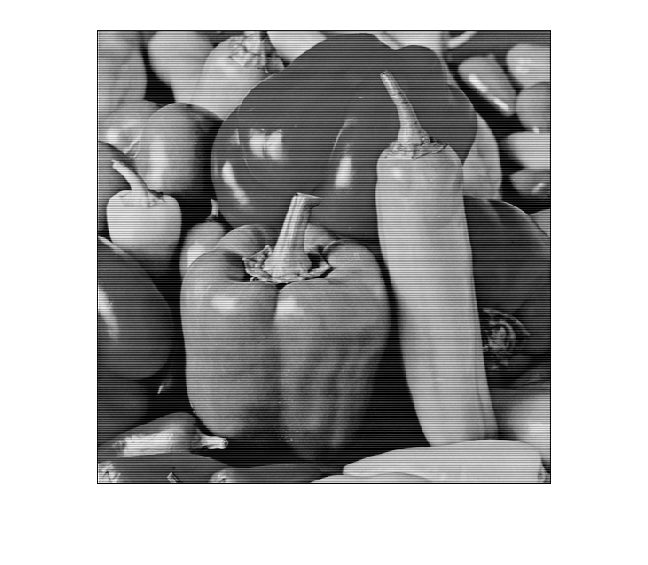


imshow(distortedImage1)

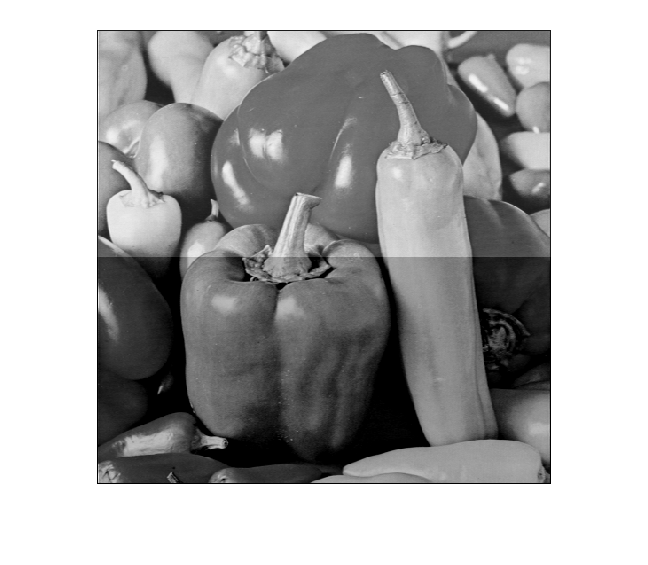

imshow(distortedImage2)


[ssimVal1, ssimMap1] = ssim(distortedImage1, pgtif);
[ssimVal2, ssimMap2] = ssim(distortedImage2, pgtif);

disp(['SSIM Value for Distortion 1: ', num2str(ssimVal1)]);

SSIM Value for Distortion 1: 0.24354


disp(['SSIM Value for Distortion 2: ', num2str(ssimVal2)]);

SSIM Value for Distortion 2: 0.85276


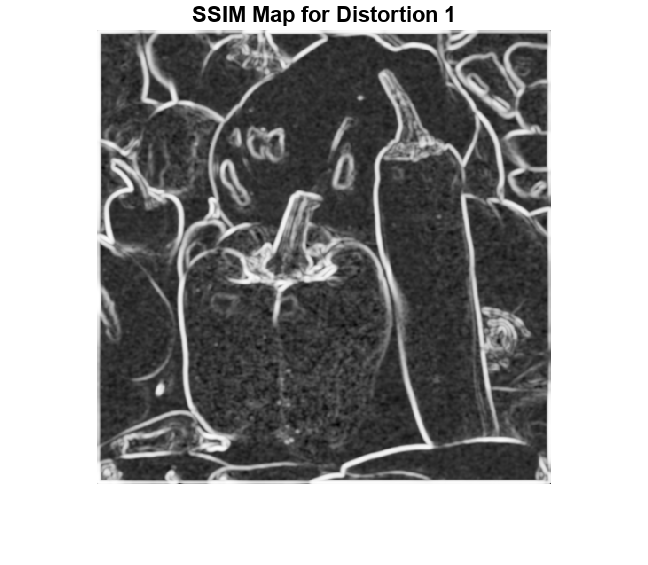


figure, imshow(ssimMap1, []);
title('SSIM Map for Distortion 1');

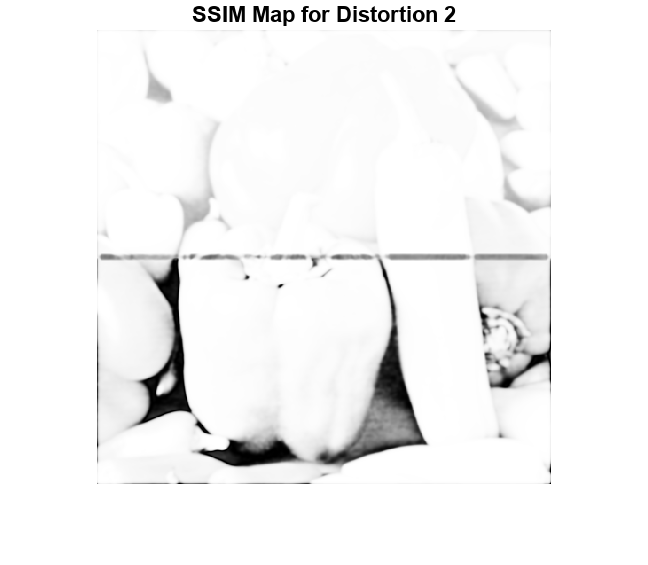

figure, imshow(ssimMap2, []);
title('SSIM Map for Distortion 2');

The maps look completely different but have the same similar SNR values as we change the same values in total. The second image should be more structuerally similar than the first.

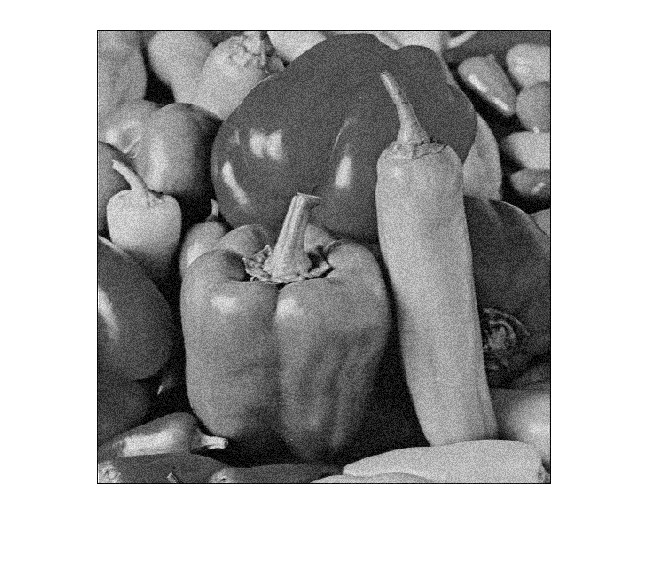

% b
dist1=pgtif+0.2*(rand(size(pgtif))-0.5);
imshow(dist1)


mysnr(dist1, abs(pgtif-dist1))

ans = 18.2586

[ssimVal, ssimMap] = ssim(dist1, pgtif);
disp(['SSIM Value for Distortion: ', num2str(ssimVal)]);

SSIM Value for Distortion: 0.43354


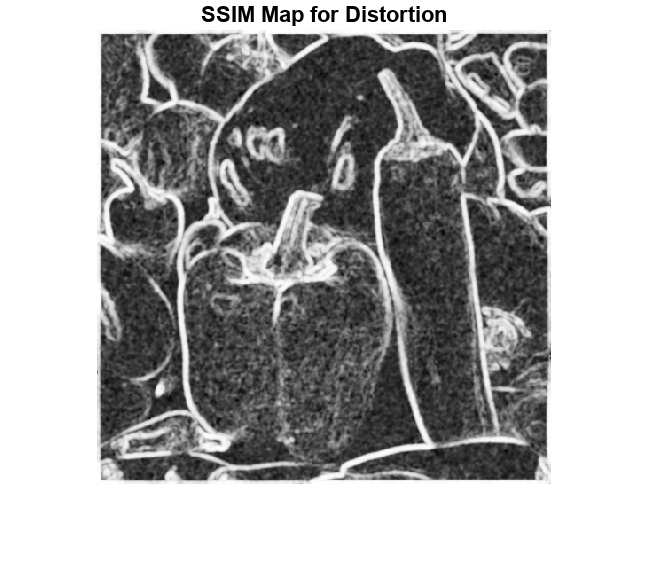

figure, imshow(ssimMap, []);
title('SSIM Map for Distortion');


f=fspecial('gauss',21,10);
result = imfilter(pgtif, f);

mysnr(result, abs(pgtif-result))

ans = 14.5892

[ssimVal, ssimMap] = ssim(result, pgtif);

disp(['SSIM Value for Distortion a: ', num2str(ssimVal)]);

SSIM Value for Distortion a: 0.67729


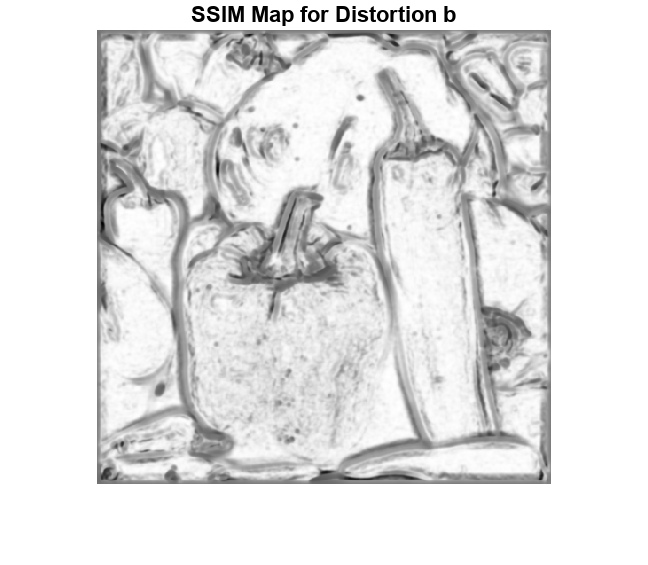


figure, imshow(ssimMap, []);
title('SSIM Map for Distortion b');